## 清理工作环境

clc;
clear;
close all;

## 读取JSON数据

daycounts=decode_JsonAPI(1);

## 解析和提取需要的数据

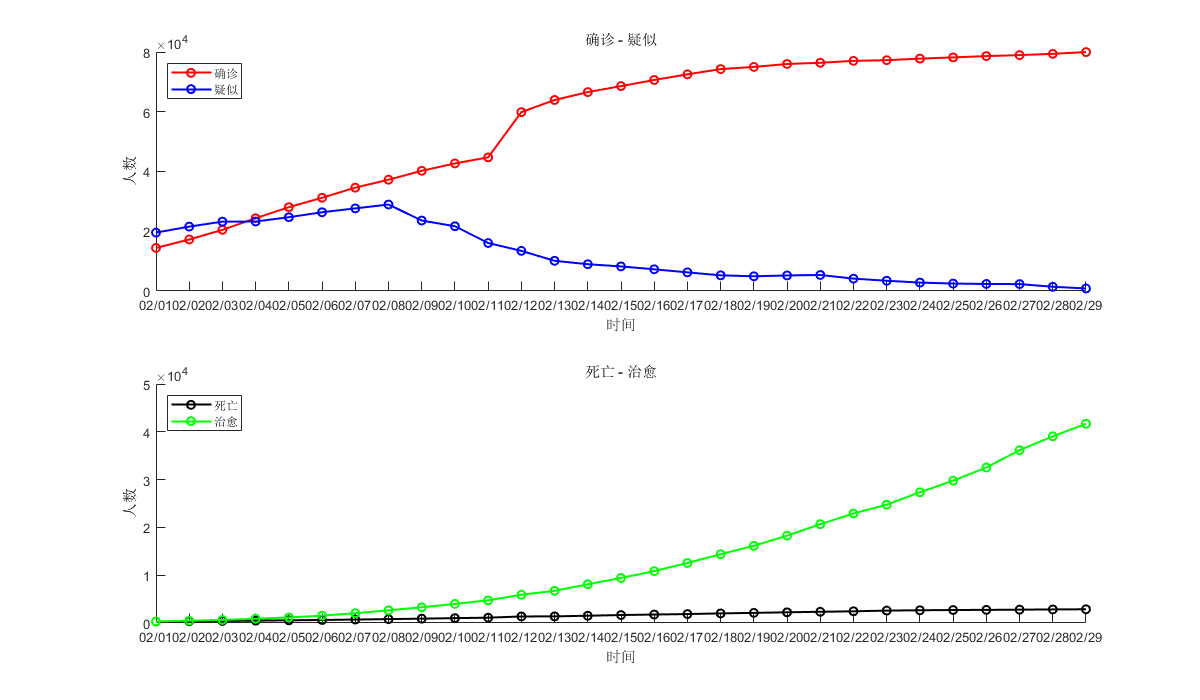

mon = 'feb';
switch mon
    case 'jan'
        startday=1;
        endday=19;
        periodstring='1月13日-1月31日';
    case 'feb'
        startday=20;
        endday=48;
        periodstring='2月1日-2月29日';
    case 'mar'
        startday=49;
        endday=79;
        periodstring='3月1日-3月31日';
end
[n_days, date_lst, D_train] = decode_DayCounts(daycounts,startday,endday);
confirm_data=D_train(:,1)';
suspect_data=D_train(:,2)';
dead_data=D_train(:,3)';
heal_data=D_train(:,4)';
draw_GeneralInfo(date_lst, confirm_data, suspect_data, dead_data, heal_data);

## 高斯拟合预测结果

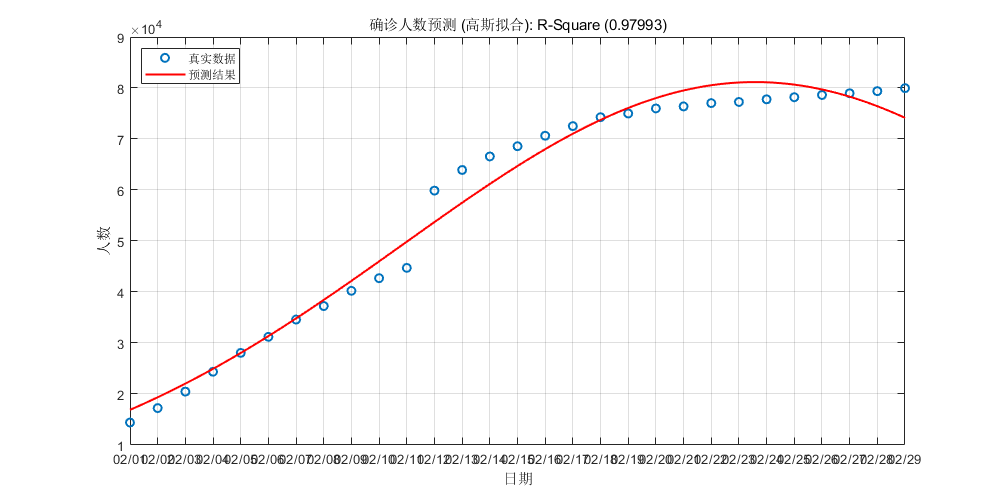

[gauss_confirm_predictor,~]=create_Fit(date_lst,confirm_data,'gauss','确诊人数预测 (高斯拟合)');

fprintf('预测次日确诊人数:%d\n',round(gauss_confirm_predictor(n_days+1)));

预测次日确诊人数:71500


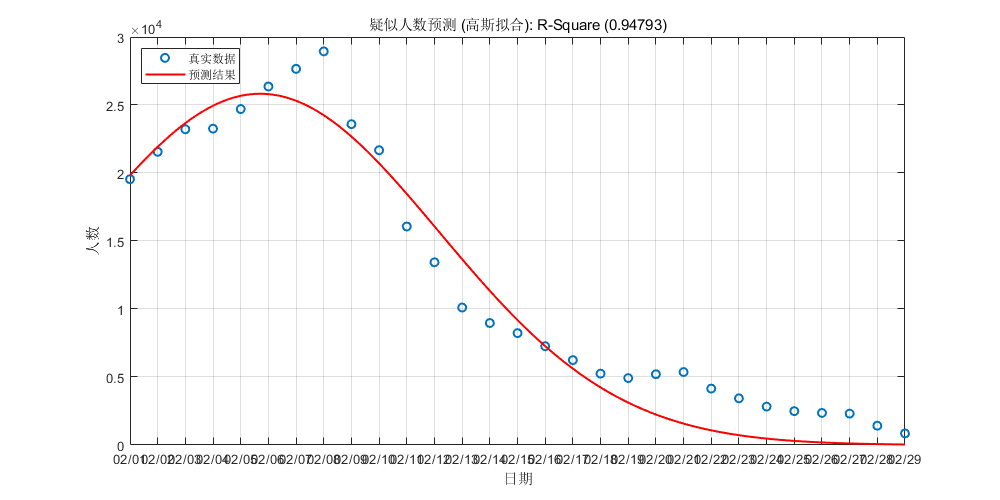

[gauss_suspect_predictor,~]=create_Fit(date_lst,suspect_data,'gauss','疑似人数预测 (高斯拟合)');

fprintf('预测次日疑似人数:%d\n',round(gauss_suspect_predictor(n_days+1)));

预测次日疑似人数:22


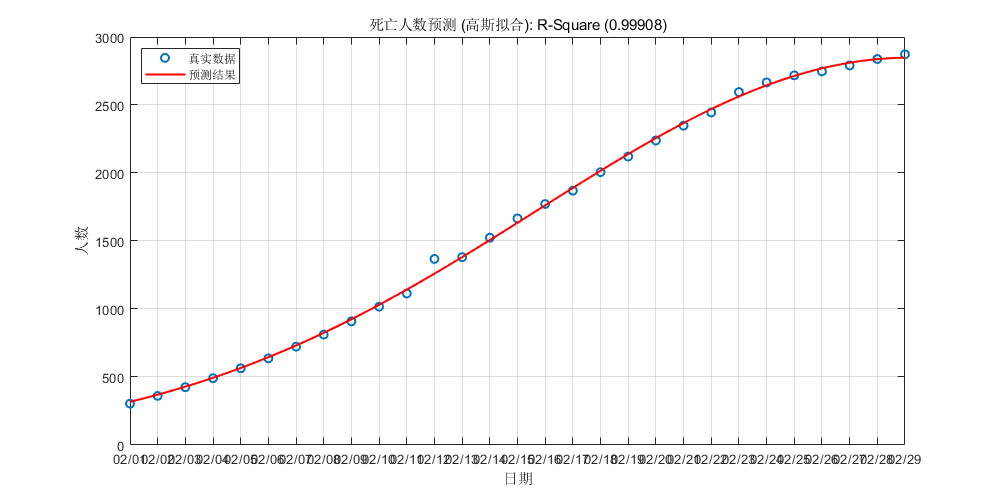

[gauss_dead_predictor,~]=create_Fit(date_lst,dead_data,'gauss','死亡人数预测 (高斯拟合)');

fprintf('预测次日死亡人数:%d\n',round(gauss_dead_predictor(n_days+1)));

预测次日死亡人数:2843


## 指数拟合预测结果

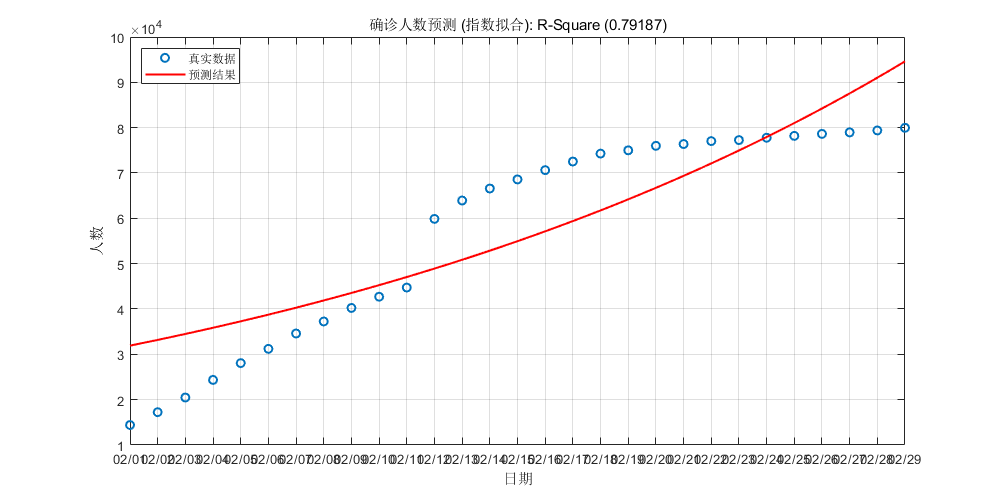

[exp_confirm_predictor,~]=create_Fit(date_lst,confirm_data,'exp','确诊人数预测 (指数拟合)');

fprintf('预测次日确诊人数:%d\n',round(exp_confirm_predictor(n_days+1)));

预测次日确诊人数:98373


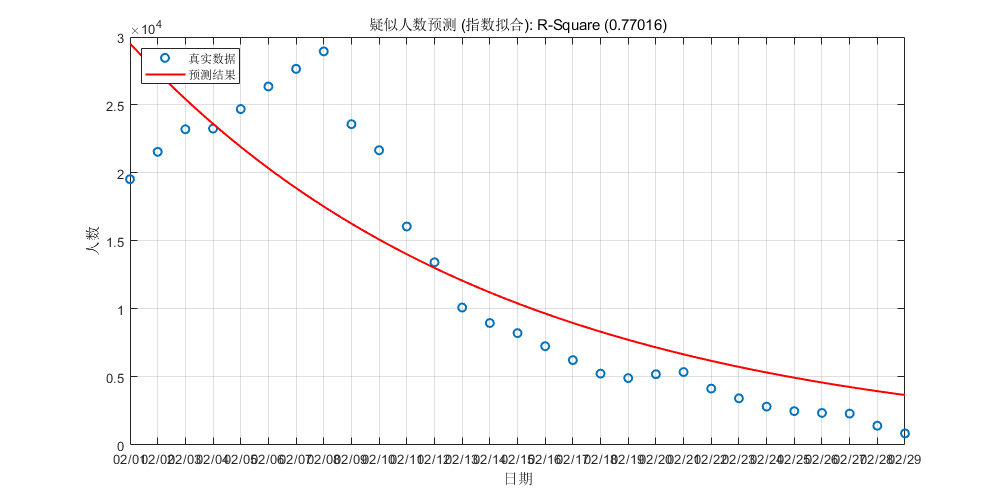


[exp_suspect_predictor,~]=create_Fit(date_lst,suspect_data,'exp','疑似人数预测 (指数拟合)');

fprintf('预测次日疑似人数:%d\n',round(exp_suspect_predictor(n_days+1)));

预测次日疑似人数:3412


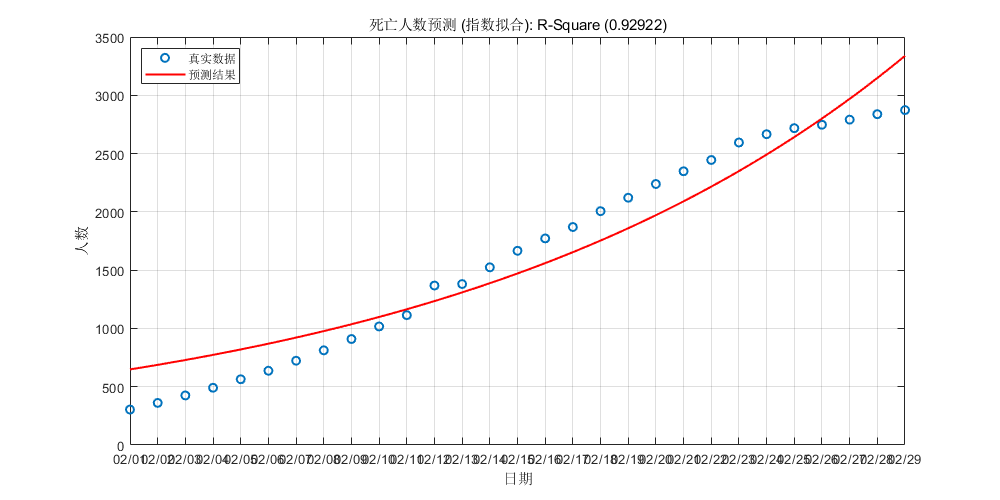


[exp_dead_predictor,~]=create_Fit(date_lst,dead_data,'exp','死亡人数预测 (指数拟合)');

fprintf('预测次日死亡人数:%d\n',round(exp_dead_predictor(n_days+1)));

预测次日死亡人数:3539


## 多项式拟合预测结果

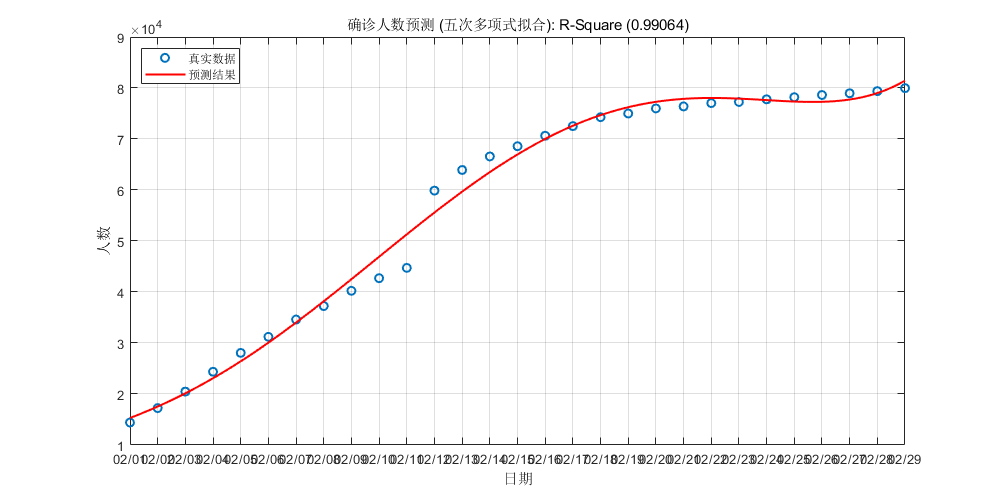

[poly_confirm_predictor,~]=create_Fit(date_lst,confirm_data,'poly','确诊人数预测 (五次多项式拟合)');

fprintf('预测次日确诊人数:%d\n',round(poly_confirm_predictor(n_days+1)));

预测次日确诊人数:85517


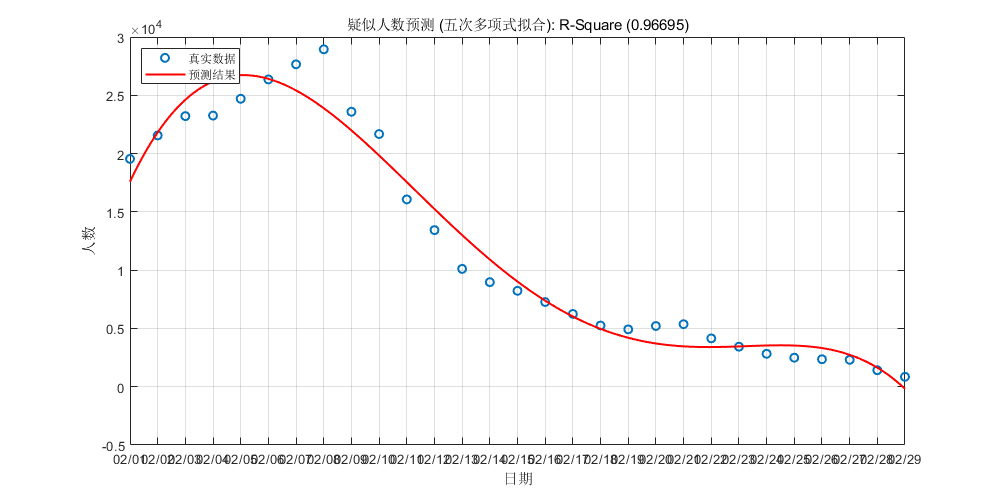


[poly_suspect_predictor,~]=create_Fit(date_lst,suspect_data,'poly','疑似人数预测 (五次多项式拟合)');

fprintf('预测次日疑似人数:%d\n',round(poly_suspect_predictor(n_days+1)));

预测次日疑似人数:-2934


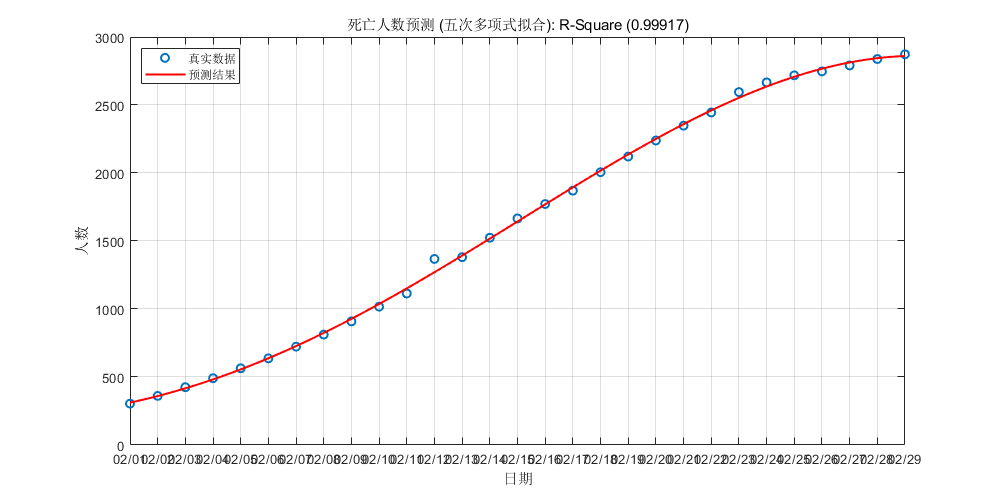


[poly_dead_predictor,~]=create_Fit(date_lst,dead_data,'poly','死亡人数预测 (五次多项式拟合)');

fprintf('预测次日死亡人数:%d\n',round(poly_dead_predictor(n_days+1)));

预测次日死亡人数:2859


## Smooth Splitting拟合预测结果

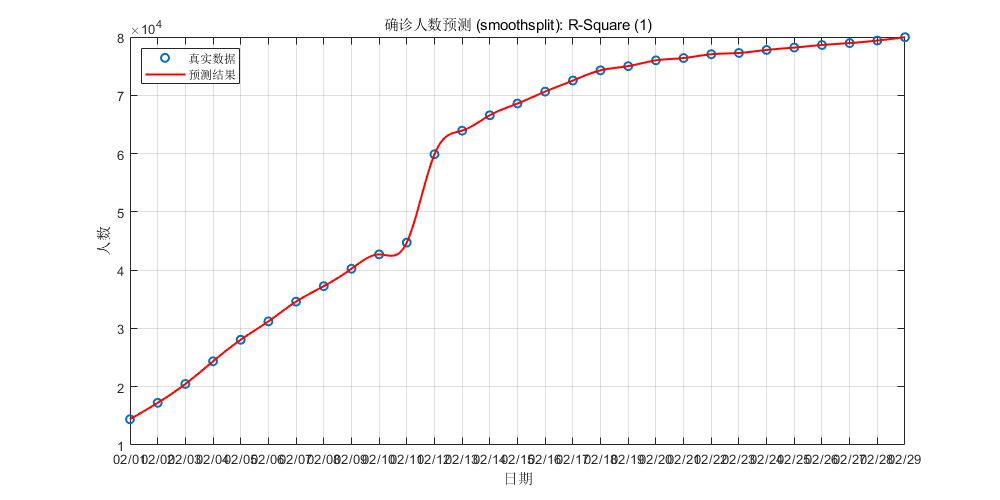

[smoothsplit_confirm_predictor,~]=create_Fit(date_lst,confirm_data,'smoothsplit','确诊人数预测 (smoothsplit)');

fprintf('预测次日确诊人数:%d\n',round(smoothsplit_confirm_predictor(n_days+1)));

预测次日确诊人数:80547


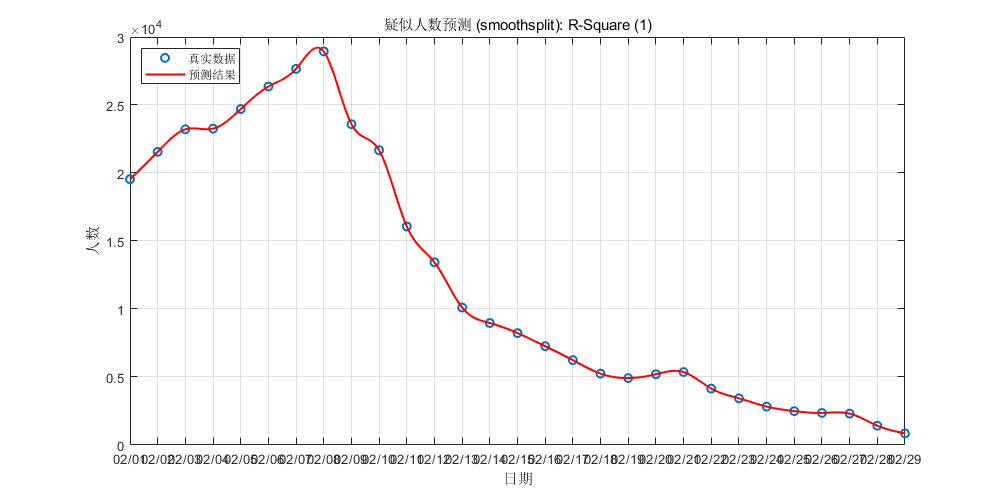


[smoothsplit_suspect_predictor,~]=create_Fit(date_lst,suspect_data,'smoothsplit','疑似人数预测 (smoothsplit)');

fprintf('预测次日疑似人数:%d\n',round(smoothsplit_suspect_predictor(n_days+1)));

预测次日疑似人数:283


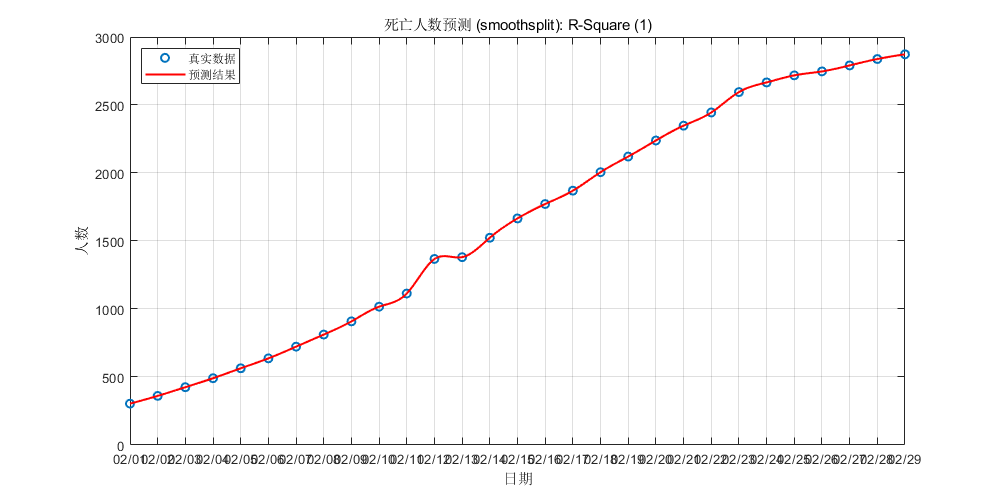


[smoothsplit_dead_predictor,~]=create_Fit(date_lst,dead_data,'smoothsplit','死亡人数预测 (smoothsplit)');

fprintf('预测次日死亡人数:%d\n',round(smoothsplit_dead_predictor(n_days+1)));

预测次日死亡人数:2908


## 神经网络预测结果

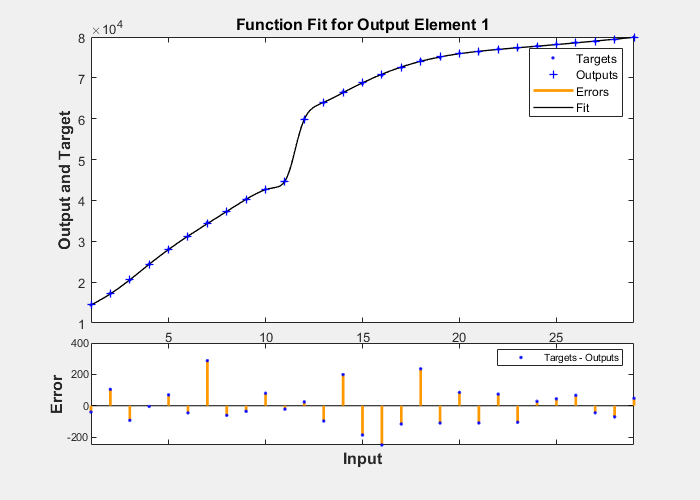

[bpnn_confirm_predictor,~]=create_NNFit(date_lst,confirm_data,5,5);

fprintf('预测次日确诊人数:%d\n',round(bpnn_confirm_predictor(n_days+1)));

预测次日确诊人数:80375


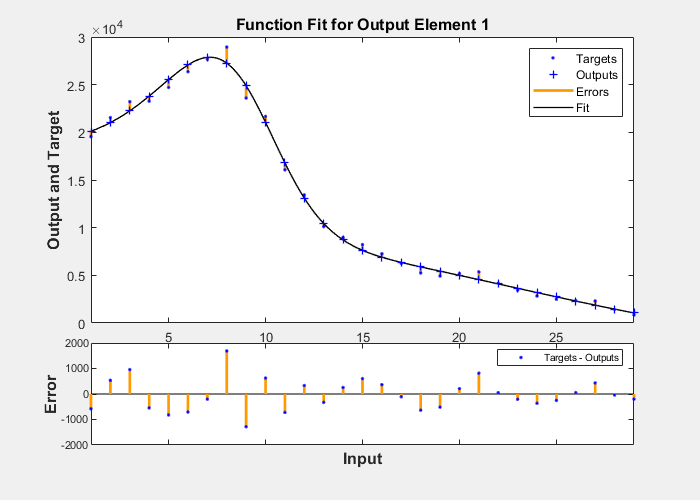


[bpnn_suspect_predictor,~]=create_NNFit(date_lst,suspect_data,5,5);

fprintf('预测次日疑似人数:%d\n',round(bpnn_suspect_predictor(n_days+1)));

预测次日疑似人数:666


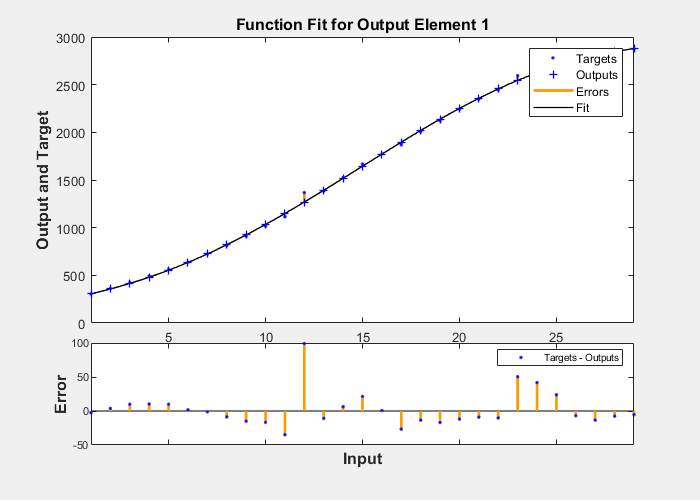


[bpnn_dead_predictor,~]=create_NNFit(date_lst,dead_data,5,5);

fprintf('预测次日死亡人数:%d\n',round(bpnn_dead_predictor(n_days+1)));

预测次日死亡人数:2903


## 自定义专家库

choose_gauss = true;
choose_exp = false;
choose_poly = true;
choose_smoothsplit = true;
choose_bpnn = true;
lst_confirm_predictors={};
lst_suspect_predictors={};
lst_dead_predictors={};
predictornames = {};
if (choose_exp)
    lst_confirm_predictors{end+1}=exp_confirm_predictor;
    lst_suspect_predictors{end+1}=exp_suspect_predictor;
    lst_dead_predictors{end+1}=exp_dead_predictor;
    predictornames{end+1} = '指数拟合'; 
end
if (choose_gauss)
    lst_confirm_predictors{end+1}=gauss_confirm_predictor;
    lst_suspect_predictors{end+1}=gauss_suspect_predictor;
    lst_dead_predictors{end+1}=gauss_dead_predictor;
    predictornames{end+1} = '高斯拟合'; 
end
if (choose_poly)
    lst_confirm_predictors{end+1}=poly_confirm_predictor;
    lst_suspect_predictors{end+1}=poly_suspect_predictor;
    lst_dead_predictors{end+1}=poly_dead_predictor;
    predictornames{end+1} = '多项式拟合'; 
end
if (choose_smoothsplit)
    lst_confirm_predictors{end+1}=smoothsplit_confirm_predictor;
    lst_suspect_predictors{end+1}=smoothsplit_suspect_predictor;
    lst_dead_predictors{end+1}=smoothsplit_dead_predictor;
    predictornames{end+1} = '平滑样条拟合'; 
end
if (choose_bpnn)
    lst_confirm_predictors{end+1}=bpnn_confirm_predictor;
    lst_suspect_predictors{end+1}=bpnn_suspect_predictor;
    lst_dead_predictors{end+1}=bpnn_dead_predictor;
    predictornames{end+1} = 'BPNN拟合'; 
end
titleprefix='预测未来三天疫情趋势';

## 专家库次日平均预测结果

fprintf('预测次日确诊人数:%d\n',meanprediction(lst_confirm_predictors,n_days+1));

预测次日确诊人数:79485


fprintf('预测次日疑似人数:%d\n',meanprediction(lst_suspect_predictors,n_days+1));

预测次日疑似人数:-491


fprintf('预测次日死亡人数:%d\n',meanprediction(lst_dead_predictors,n_days+1));

预测次日死亡人数:2878


## 专家库三天预测

## 设置测试数据

[~, ~, D_test] = decode_DayCounts(daycounts,endday+1,endday+3);
test_confirm_data=D_test(:,1)';
test_suspect_data=D_test(:,2)';
test_dead_data=D_test(:,3)';

### 确诊人数预测

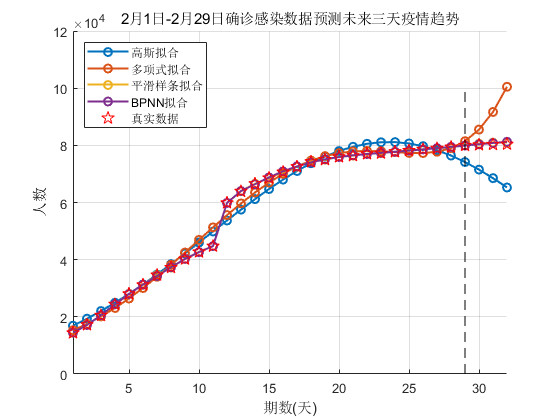

predict_LongTerm(confirm_data,test_confirm_data,lst_confirm_predictors,predictornames,[periodstring '确诊感染数据' titleprefix]);

### 疑似人数预测

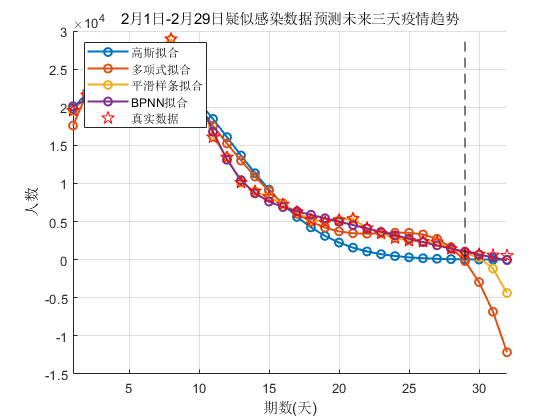

predict_LongTerm(suspect_data,test_suspect_data,lst_suspect_predictors,predictornames,[periodstring '疑似感染数据' titleprefix]);

### 死亡人数预测

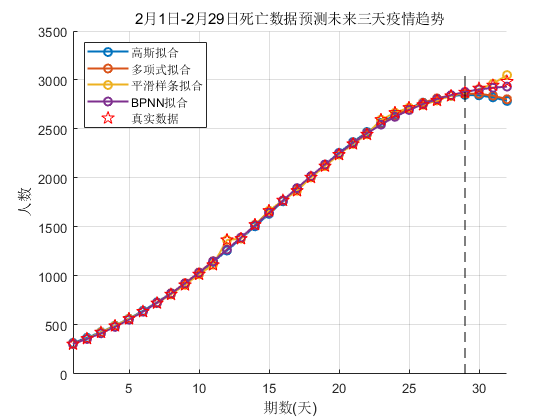

predict_LongTerm(dead_data,test_dead_data,lst_dead_predictors,predictornames,[periodstring '死亡数据' titleprefix]);